# Problem 1:

## (a)

A = [3,0; ...
     4,5];
 [U,Sig,V] = svd(A);
 Q = U*V'

Q =    0.894427190999916  -0.447213595499958
   0.447213595499958   0.894427190999916


 S = V*Sig*V'

S =    4.472135954999579   2.236067977499790
   2.236067977499790   4.472135954999579


## (b) 

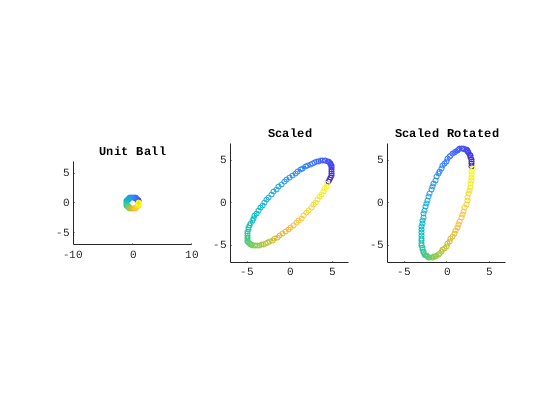

 % Generate unit ball
 theta = linspace(0,2*pi,100);
 circ = [cos(theta); sin(theta)];
 
 figure();
 subplot(1,3,1)
 scatter(circ(1,:),circ(2,:),15,theta)
 title('Unit Ball')
 axis equal
 xlim([-10,10])
 ylim([-7,7])
 
 subplot(1,3,2)
 circ1 = S*circ;
 scatter(circ1(1,:),circ1(2,:),15,theta)
 title('Scaled')
 axis equal
 xlim([-7,7])
 ylim([-7,7])
 
 subplot(1,3,3)
 circ2 = Q*circ1;
 scatter(circ2(1,:),circ2(2,:),15,theta)
 title('Scaled Rotated','FontSize',4)
 axis equal
 xlim([-7,7])
 ylim([-7,7])

From the plots above, we can clearly see the different actions of each matrix in the polar decomposition of A. The first plot shows the initial unit ball before any transformation. The second plot shows the unit ball scales from the $S$. Finally, the third plot shows the rotation of the $Q$ matrix.

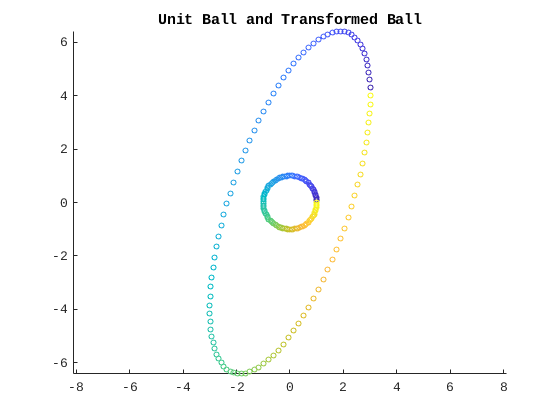

 figure()
 scatter(circ(1,:),circ(2,:),15,theta)
 hold on
 circA = A*circ;
 scatter(circA(1,:),circA(2,:),15,theta)
 title('Unit Ball and Transformed Ball')
 axis equal

The plot above confirms that the set of rotations and scaling in the polar decomposition do lead to the end result of transforming the unit ball with $A$. Thus, we can decompose a matrix into two steps, a rotation and a scaling. If we want to go further, we can decompose $A$ into $SQ$ where $S$ scales and $Q$ rotates. The $S$ and $Q$ in this case are given by $A = U \Sigma V^T = U \Sigma U^T U V^T = (U \Sigma U^T)(UV^T) = (SQ)$. Thus we are able to decompose $A$ into a rotation and a scaling in the order of our choosing! Cool.

# Problem 2:

If $A$ is a $2\times 2$ matrix with $\sigma_1 \geq \sigma_2 > 0$.

We know the inverse of a matrix has singular values equal to the reciprocal of the singular values of initial matrix. In other words, the singular values for $A^{-1}$ are $\frac{1}{\sigma_2} \geq \frac{1}{\sigma_1} > 0$. And so, we have

$||A^{-1}||_2 = \frac{1}{\sigma_2}$,

$||A^{-1}||_F = \sqrt{\left(\frac{1}{\sigma_2}\right)^2 + \left(\frac{1}{\sigma_1}\right)^2}$.